Loading in the files

nearFieldPulse = load("NearFieldPulse.mat");
profile_AZ_7cm_full = load("profile_AZ_7cm_Full.mat");
profile_AZ_7cm_reduced = load("profile_AZ_7cm_reduced.mat");
profile_EL_7cm_full = load("profile_EL_7cm_Full.mat");
profile_EL_7cm_reduced = load("profile_EL_7cm_reduced.mat");
pulse_7cm_0dB_10x_aver = load("pulse_7cm_0dB_10x_aver.mat");
pulse_7cm_m8dB_10x_aver = load("pulse_7cm_-8dB_10x_aver.mat");
pulse_7cm_m14dB_10x_aver = load("pulse_7cm_-14dB_10x_aver.mat");
pulse_7cm_m14dB_no_aver = load("pulse_7cm_-14dB_no_aver.mat");
z_axis_12dB = load("z_axis_12dB.mat"); 


Fetching usefull information from the structs

pulse14_rf_noA = pulse_7cm_m14dB_no_aver.RF;
pulse14_rf_10A = pulse_7cm_m14dB_10x_aver.RF;
pulse8_rf_10A = pulse_7cm_m8dB_10x_aver.RF;
pulse0_rf_10A = pulse_7cm_0dB_10x_aver.RF;

time_pulse14_noA = linspace(pulse_7cm_m14dB_no_aver.Time,length(pulse14_rf_noA)*pulse_7cm_0dB_10x_aver.Ts,length(pulse14_rf_noA));
time_pulse14_10A = linspace(pulse_7cm_m14dB_10x_aver.Time,length(pulse14_rf_10A)*pulse_7cm_m14dB_10x_aver.Ts,length(pulse14_rf_10A));
time_pulse8_10A = linspace(pulse_7cm_m8dB_10x_aver.Time,length(pulse8_rf_10A)*pulse_7cm_m8dB_10x_aver.Ts,length(pulse8_rf_10A));
time_pulse0_10A = linspace(pulse_7cm_0dB_10x_aver.Time,length(pulse0_rf_10A)*pulse_7cm_0dB_10x_aver.Ts,length(pulse0_rf_10A));


%since the length of all pulses are the same her I will just use one for
%the number of samples.
num_samples = length(pulse14_rf_noA);
signal_stop_sig = idivide(num_samples,int16(4));
start_sig = 250;
noise1_start = 1;
noise1_end = 249;
noise2_start = signal_stop_sig + 1;
noise2_end = num_samples;

Task 1 pulse in focus 

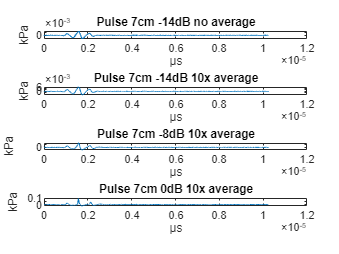

subplot(4,1,1);
plot(time_pulse14_noA,pulse14_rf_noA);
title('Pulse 7cm -14dB no average');

xlabel("\mus");
ylabel("kPa");

subplot(4,1,2);
plot(time_pulse14_10A,pulse14_rf_10A);
title('Pulse 7cm -14dB 10x average');
xlabel("\mus");
ylabel("kPa");

subplot(4,1,3);
plot(time_pulse8_10A,pulse8_rf_10A);
title('Pulse 7cm -8dB 10x average');
xlabel("\mus");
ylabel("kPa");

subplot(4,1,4);
plot(time_pulse0_10A,pulse0_rf_10A);
title('Pulse 7cm 0dB 10x average');
xlabel("\mus");
ylabel("kPa");


clf("reset");

Task 2 Frequency spectra, signal to noise ratio.

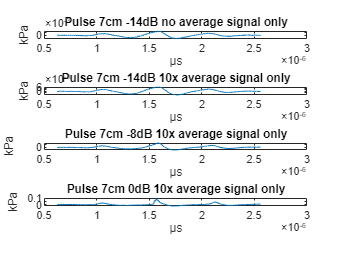

subplot(4,1,1);
plot(time_pulse14_noA(start_sig:signal_stop_sig),pulse14_rf_noA(start_sig:signal_stop_sig));
title('Pulse 7cm -14dB no average signal only');

xlabel("\mus");
ylabel("kPa");

subplot(4,1,2);
plot(time_pulse14_10A(start_sig:signal_stop_sig),pulse14_rf_10A(start_sig:signal_stop_sig));
title('Pulse 7cm -14dB 10x average signal only');
xlabel("\mus");
ylabel("kPa");

subplot(4,1,3);
plot(time_pulse8_10A(start_sig:signal_stop_sig),pulse8_rf_10A(start_sig:signal_stop_sig));
title('Pulse 7cm -8dB 10x average signal only');
xlabel("\mus");
ylabel("kPa");

subplot(4,1,4);
plot(time_pulse0_10A(start_sig:signal_stop_sig),pulse0_rf_10A(start_sig:signal_stop_sig));
title('Pulse 7cm 0dB 10x average signal only');
xlabel("\mus");
ylabel("kPa");

clf("reset");

Just wanted to plot the noise too, the weird part is where the signal should be.

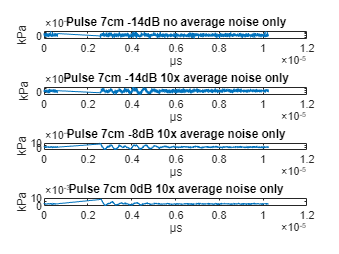

subplot(4,1,1);
plot(time_pulse14_noA([noise1_start:noise1_end noise2_start:noise2_end]),pulse14_rf_noA([noise1_start:noise1_end noise2_start:noise2_end]));
title('Pulse 7cm -14dB no average noise only');

xlabel("\mus");
ylabel("kPa");

subplot(4,1,2);
plot(time_pulse14_10A([noise1_start:noise1_end noise2_start:noise2_end]),pulse14_rf_10A([noise1_start:noise1_end noise2_start:noise2_end]));
title('Pulse 7cm -14dB 10x average noise only');
xlabel("\mus");
ylabel("kPa");

subplot(4,1,3);
plot(time_pulse8_10A([noise1_start:noise1_end noise2_start:noise2_end]),pulse8_rf_10A([noise1_start:noise1_end noise2_start:noise2_end]));
title('Pulse 7cm -8dB 10x average noise only');
xlabel("\mus");
ylabel("kPa");

subplot(4,1,4);
plot(time_pulse0_10A([noise1_start:noise1_end noise2_start:noise2_end]),pulse0_rf_10A([noise1_start:noise1_end noise2_start:noise2_end]));
title('Pulse 7cm 0dB 10x average noise only');
xlabel("\mus");
ylabel("kPa");


clf("reset");

Setting parameters.

Nfft = 2048; %could be changed.
fs = 1/pulse_7cm_0dB_10x_aver.Ts; %same for everyone

Spectrum for signal

freqtab = linspace(-0.5, 0.5, Nfft+1)*fs; freqtab(end) = [];

pow_spect_pulse14_rf_noA_sig = 20*log10( abs( fftshift( fft( pulse14_rf_noA(start_sig:signal_stop_sig), Nfft) ) ) );


pow_spect_pulse14_rf_10A_sig = 20*log10( abs( fftshift( fft( pulse14_rf_10A(start_sig:signal_stop_sig), Nfft) ) ) );


pow_spect_pulse8_rf_10A_sig = 20*log10( abs( fftshift( fft( pulse8_rf_10A(start_sig:signal_stop_sig), Nfft) ) ) );


pow_spect_pulse0_rf_10A_sig = 20*log10( abs( fftshift( fft( pulse0_rf_10A(start_sig:signal_stop_sig), Nfft) ) ) );

Spectrum for noise



pow_spect_pulse14_rf_noA_noise  = 20*log10( abs( fftshift( fft( pulse14_rf_noA([noise1_start:noise1_end noise2_start:noise2_end]), Nfft) ) ) );


pow_spect_pulse14_rf_10A_noise = 20*log10( abs( fftshift( fft( pulse14_rf_10A([noise1_start:noise1_end noise2_start:noise2_end]), Nfft) ) ) );


pow_spect_pulse8_rf_10A_noise  = 20*log10( abs( fftshift( fft( pulse8_rf_10A([noise1_start:noise1_end noise2_start:noise2_end]), Nfft) ) ) );


pow_spect_pulse0_rf_10A_noise  = 20*log10( abs( fftshift( fft( pulse0_rf_10A([noise1_start:noise1_end noise2_start:noise2_end]), Nfft) ) ) );

Spectrum plot signal

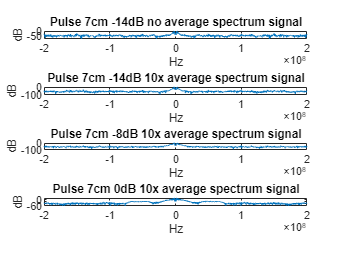

subplot(4,1,1);
plot(freqtab,pow_spect_pulse14_rf_noA_sig);
title('Pulse 7cm -14dB no average spectrum signal');
xlabel("Hz");
ylabel("dB");

subplot(4,1,2);
plot(freqtab,pow_spect_pulse14_rf_10A_sig);
title('Pulse 7cm -14dB 10x average spectrum signal');
xlabel("Hz");
ylabel("dB");

subplot(4,1,3);
plot(freqtab,pow_spect_pulse8_rf_10A_sig);
title('Pulse 7cm -8dB 10x average spectrum signal');
xlabel("Hz");
ylabel("dB");

subplot(4,1,4);
plot(freqtab,pow_spect_pulse0_rf_10A_sig);
title('Pulse 7cm 0dB 10x average spectrum signal');
xlabel("Hz");
ylabel("dB");


clf("reset");

Spectrum plot noise

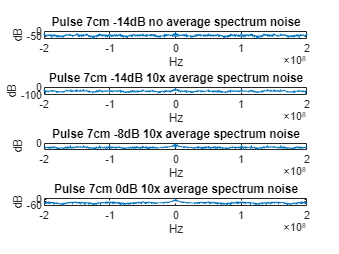

subplot(4,1,1);
plot(freqtab,pow_spect_pulse14_rf_noA_noise);
title('Pulse 7cm -14dB no average spectrum noise');
xlabel("Hz");
ylabel("dB");

subplot(4,1,2);
plot(freqtab,pow_spect_pulse14_rf_10A_noise);
title('Pulse 7cm -14dB 10x average spectrum noise');
xlabel("Hz");
ylabel("dB");

subplot(4,1,3);
plot(freqtab,pow_spect_pulse8_rf_10A_noise);
title('Pulse 7cm -8dB 10x average spectrum noise');
xlabel("Hz");
ylabel("dB");

subplot(4,1,4);
plot(freqtab,pow_spect_pulse0_rf_10A_noise);
title('Pulse 7cm 0dB 10x average spectrum noise');
xlabel("Hz");
ylabel("dB");


clf("reset");

Just plotting the end of the noise, since it gave some weird output when i used the noise first and after.

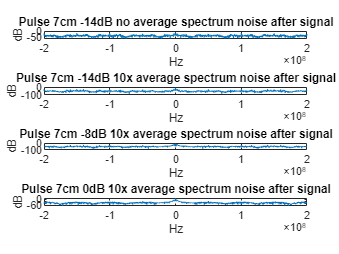

%freqtab = linspace(-0.5, 0.5, Nfft+1)*fs; freqtab(end) = [];
pow_spect_pulse14_rf_noA_noise1  = 20*log10( abs( fftshift( fft( pulse14_rf_noA(noise2_start:noise2_end), Nfft) ) ) );

%freqtab = linspace(-0.5, 0.5, Nfft+1)*fs; freqtab(end) = [];
pow_spect_pulse14_rf_10A_noise1 = 20*log10( abs( fftshift( fft( pulse14_rf_10A(noise2_start:noise2_end), Nfft) ) ) );

%freqtab = linspace(-0.5, 0.5, Nfft+1)*fs; freqtab(end) = [];
pow_spect_pulse8_rf_10A_noise1  = 20*log10( abs( fftshift( fft( pulse8_rf_10A(noise2_start:noise2_end), Nfft) ) ) );

%freqtab = linspace(-0.5, 0.5, Nfft+1)*fs; freqtab(end) = [];
pow_spect_pulse0_rf_10A_noise1  = 20*log10( abs( fftshift( fft( pulse0_rf_10A(noise2_start:noise2_end), Nfft) ) ) );

subplot(4,1,1);
plot(freqtab,pow_spect_pulse14_rf_noA_noise1);
title('Pulse 7cm -14dB no average spectrum noise after signal');
xlabel("Hz");
ylabel("dB");

subplot(4,1,2);
plot(freqtab,pow_spect_pulse14_rf_10A_noise1);
title('Pulse 7cm -14dB 10x average spectrum noise after signal');
xlabel("Hz");
ylabel("dB");

subplot(4,1,3);
plot(freqtab,pow_spect_pulse8_rf_10A_noise1);
title('Pulse 7cm -8dB 10x average spectrum noise after signal');
xlabel("Hz");
ylabel("dB");

subplot(4,1,4);
plot(freqtab,pow_spect_pulse0_rf_10A_noise1);
title('Pulse 7cm 0dB 10x average spectrum noise after signal');
xlabel("Hz");
ylabel("dB");


clf("reset");

What frequency yields the strongest signal? What is the approximate spectral signal to noise ratio (spectral SNR) for the different pulses on this frequency? Spectral SNR here refers to the difference in dB between a signal component and the noise floor in the spectrum.

A:

By looking at the different plots, the SNR seems to be around 50 dB +-5 dB

[pow_spect_pulse14_rf_noA_sig_max,idx1] = max(pow_spect_pulse14_rf_noA_sig);
[pow_spect_pulse14_rf_10A_sig_max, idx2] = max(pow_spect_pulse14_rf_10A_sig);
[pow_spect_pulse8_rf_10A_sig_max,idx3] = max(pow_spect_pulse8_rf_10A_sig);
[pow_spect_pulse0_rf_10A_sig_max, idx4] = max(pow_spect_pulse0_rf_10A_sig);
fprintf('Max amplitude of spectrum -14dB no average is %4.2f at frequency %8.2f Hz',pow_spect_pulse14_rf_noA_sig_max, abs(freqtab(idx1)));

Max amplitude of spectrum -14dB no average is -0.33 at frequency 1953125.00 Hz

fprintf('Max amplitude of spectrum -14dB 10x average is %4.2f at frequency %8.2f Hz',pow_spect_pulse14_rf_10A_sig_max, abs(freqtab(idx2)));

Max amplitude of spectrum -14dB 10x average is -0.25 at frequency 2148437.50 Hz

fprintf('Max amplitude of spectrum -8dB 10x average is %4.2f at frequency %8.2f Hz',pow_spect_pulse8_rf_10A_sig_max, abs(freqtab(idx3)));

Max amplitude of spectrum -8dB 10x average is 6.31 at frequency 1953125.00 Hz

fprintf('Max amplitude of spectrum 0dB 10x average is %4.2f at frequency %8.2f Hz',pow_spect_pulse0_rf_10A_sig_max, abs(freqtab(idx4)));

Max amplitude of spectrum 0dB 10x average is 14.18 at frequency 1953125.00 Hz

If the noise is white, it should have approximately equal power for all frequencies. Is the noise white? If not, can you explain why? How does this influence the SNR estimates above? 

A:

There are some white noise, but you can see some reflection/perodic pattern in the noise, expecially in the 0dB one.

How much SNR should you gain when averaging over 10 pulses? Do you see the same gain in the results?

A:

Gained around 10dB compared to no averaging.

Measure the peak power at the fundamental frequency when increasing power from -14dB to -8db to 0dB? Is this as expected? 

A:

it increases a bit but also gets more sideloobs.

Measure the peak power of the second harmonic frequency when increasing power from -14 dB to -8dB to 0dB. Compare to the corresponding results for the fundamental frequency. Can you explain your observations? How does this affect the pulse shape?

A: 

Not sure how to do it, doesnt look like it is alot of harmonics.

Task 3

profile_AZ_7cm_full_rf = profile_AZ_7cm_full.RF;
profile_AZ_7cm_full_pos = profile_AZ_7cm_full.Position;
profile_AZ_7cm_full_ts = profile_AZ_7cm_full.Ts;

wprofile_EL_7cm_full_pos = profile_EL_7cm_full.Position;
profile_EL_7cm_full_ts = profile_EL_7cm_full.Ts;

AZ_intensity = sum(profile_AZ_7cm_full_rf.^2);
EL_intensity = sum(profile_EL_7cm_full_rf.^2);

AZ_intensity_db = 10*log10(AZ_intensity);
EL_intensity_db = 10*log10(EL_intensity);

max_int_AL_db = max(AZ_intensity_db);
max_int_EL_db = max(EL_intensity_db);

fprintf("Maximum intensity for AL %4.2f dB, and for EL %8.2f dB",max_int_AL_db,max_int_EL_db);

Maximum intensity for AL 28.87 dB, and for EL    27.41 dB


beam_AL_end_list = find(AZ_intensity_db < (max_int_AL_db-6));
beam_AL_end_idx = beam_AL_end_list(61);

beam_EL_end_list = find(EL_intensity_db < (max_int_EL_db-6));
beam_EL_end_idx = beam_EL_end_list(55);

%the index is found by just checking the list, didnt have time to find
%another solution.
%width is then for EL 96-55 = 41 mm
%width for AL is 82-61 = 21 mm

fprintf("The width of beam for AL is: 21 mm and for EL: 41 mm");

The width of beam for AL is: 21 mm and for EL: 41 mm

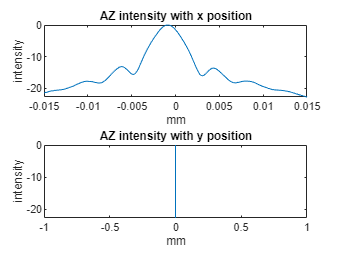

subplot(2,1,1);
plot(profile_AZ_7cm_full_pos(1,:),AZ_intensity_db-max(AZ_intensity_db(:)));
title("AZ intensity with x position");
ylabel("intensity");
xlabel("mm");

subplot(2,1,2);
plot(profile_AZ_7cm_full_pos(2,:),AZ_intensity_db-max(AZ_intensity_db(:)));
title("AZ intensity with y position");
ylabel("intensity");
xlabel("mm");

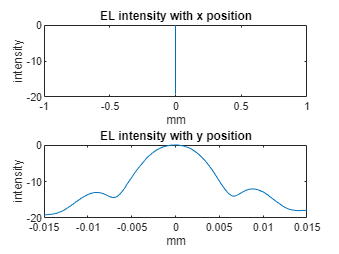


clf("reset");

subplot(2,1,1);
plot(profile_EL_7cm_full_pos(1,:),EL_intensity_db-max(EL_intensity_db(:)));
title("EL intensity with x position");
ylabel("intensity");
xlabel("mm");

subplot(2,1,2);
plot(profile_EL_7cm_full_pos(2,:),EL_intensity_db-max(EL_intensity_db(:)));
title("EL intensity with y position");
ylabel("intensity");
xlabel("mm");


clf("reset");

Calculate the wavelength λ and the F-number in azimuth and elevation.

A:

Not quite sure if this is the correct way, but D_f = 1.2 F# * \lamda 

for Azimuth

F# = F/D = 7 cm / 1.853 cm = 3.78 cm (assume D the 1.853)

\lamda = 2.1/(1.2*3.78) = 0.463

for elevation

same calculation but with new D_f and and D

F# = F/D = 7 cm / 1.853 cm = 5.83 cm

\lamda = 4.1/(1.2*5.83) = 0.586 

According to theory, which mathematical function should describe the beam profiles? Create a suitable position axis and plot the power of this function vs position in Matlab, using logarithmic scale. Estimate the beam width, distance to the sidelobes, and the sidelobe level. If you have not considered this already, how should this function be rescaled (along the x-axis) to match the measured beam profiles in azimuth and elevation.

Are the measured beam profiles as expected? (Beam width, distance to sidelobes, sidelobe level).

Task 4

profile_AZ_7cm_reduced_rf = profile_AZ_7cm_reduced.RF;
profile_AZ_7cm_reduced_pos = profile_AZ_7cm_reduced.Position;
profile_AZ_7cm_reduced_ts = profile_AZ_7cm_reduced.Ts;

profile_EL_7cm_reduced_rf = profile_EL_7cm_reduced.RF;
profile_EL_7cm_reduced_pos = profile_EL_7cm_reduced.Position;
profile_EL_7cm_reduced_ts = profile_EL_7cm_reduced.Ts;

AZ_intensity_r = sum(profile_AZ_7cm_reduced_rf.^2);
EL_intensity_r = sum(profile_EL_7cm_reduced_rf.^2);

AZ_intensity_db_r = 10*log10(AZ_intensity_r);
EL_intensity_db_r = 10*log10(EL_intensity_r);

max_int_AL_db_r = max(AZ_intensity_db_r);
max_int_EL_db_r = max(EL_intensity_db_r);

fprintf("Maximum intensity for AL %4.2f dB, and for EL %8.2f dB",max_int_AL_db_r,max_int_EL_db_r);

Maximum intensity for AL 23.17 dB, and for EL    22.92 dB


beam_AL_end_list_r = find(AZ_intensity_db_r < (max_int_AL_db_r-6));
beam_AL_end_idx_r = beam_AL_end_list_r(61);

beam_EL_end_list_r = find(EL_intensity_db_r < (max_int_EL_db_r-6));
beam_EL_end_idx_r = beam_EL_end_list_r(55);

%the index is found by just checking the list, didnt have time to find
%another solution.
%width is then for EL 94-57 = 37 mm
%width for AL is 94-49 = 45 mm

fprintf("The width of beam for AL is: 45 mm and for EL: 37 mm");

The width of beam for AL is: 45 mm and for EL: 37 mm

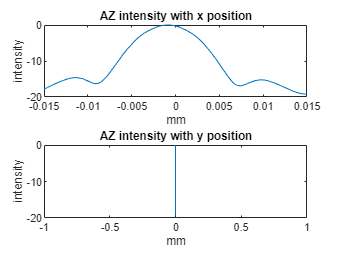

subplot(2,1,1);
plot(profile_AZ_7cm_reduced_pos(1,:),AZ_intensity_db_r-max(AZ_intensity_db_r(:)));
title("AZ intensity with x position");
ylabel("intensity");
xlabel("mm");

subplot(2,1,2);
plot(profile_AZ_7cm_reduced_pos(2,:),AZ_intensity_db_r-max(AZ_intensity_db_r(:)));
title("AZ intensity with y position");
ylabel("intensity");
xlabel("mm");

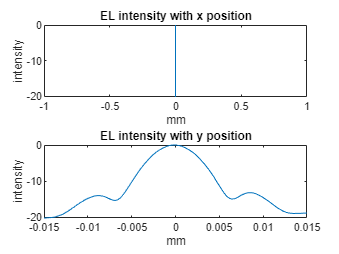


clf("reset");

subplot(2,1,1);
plot(profile_EL_7cm_reduced_pos(1,:),EL_intensity_db_r-max(EL_intensity_db_r(:)));
title("EL intensity with x position");
ylabel("intensity");
xlabel("mm");

subplot(2,1,2);
plot(profile_EL_7cm_reduced_pos(2,:),EL_intensity_db_r-max(EL_intensity_db_r(:)));
title("EL intensity with y position");
ylabel("intensity");
xlabel("mm");


clf("reset");

Task 5

Didnt quite understand which file I should plot (and was to late to ask), but would do the same as over. 

Task 6

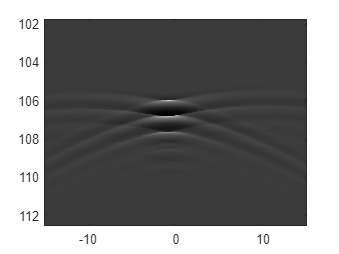

load('profile_Az_7cm_full.mat');
timescale=Position(4,1)+Ts(1)*[1:size(RF,1)]; %Ts= Sampling rate
speedofsound=1500;%m/s
depthscale=timescale*speedofsound*1e3;%mm
azimutpositionscale=Position(1,:)*1e3; %mm
imagesc(azimutpositionscale,depthscale,RF); %Neg. pressure dark
colormap(gray); 

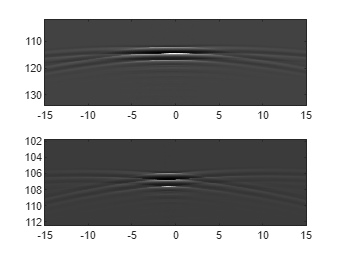

subplot(2,1,1);

load('profile_AZ_7cm_reduced.mat');
timescale=Position(4,1)+Ts(1)*[1:size(RF,1)]; %Ts= Sampling rate
speedofsound=1500;%m/s
depthscale=timescale*speedofsound*1e3;%mm
azimutpositionscale=Position(1,:)*1e3; %mm
imagesc(azimutpositionscale,depthscale,RF); %Neg. pressure dark
colormap(gray); 

subplot(2,1,2);
load('profile_Az_7cm_full.mat');
timescale=Position(4,1)+Ts(1)*[1:size(RF,1)]; %Ts= Sampling rate
speedofsound=1500;%m/s
depthscale=timescale*speedofsound*1e3;%mm
azimutpositionscale=Position(1,:)*1e3; %mm
imagesc(azimutpositionscale,depthscale,RF); %Neg. pressure dark
colormap(gray); 

The edges get less sharp when it is reduced, and they get streched.